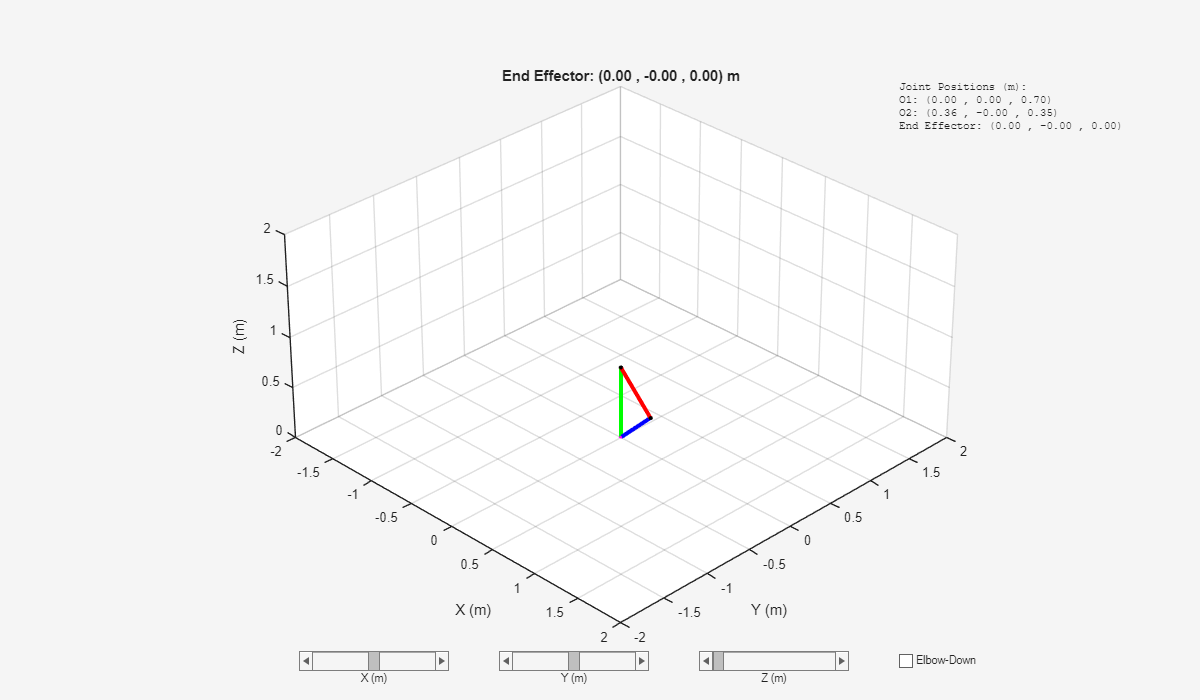

clc; clear; close all;

%% --- Figure setup ---
f1 = figure('Name','3R Anthropomorphic Arm (IK)','NumberTitle','off','Position',[100 100 1200 700]);
ax = axes('Parent',f1);
axis equal; grid on; hold on;
xlabel('X (m)'); ylabel('Y (m)'); zlabel('Z (m)');
xlim([-2 2]); ylim([-2 2]); zlim([0 2]);
view(45,30); camproj('perspective');
title('Anthropomorphic Arm Visualization');

%% --- Link visuals ---
r = 0.02; % joint sphere radius
N = 30;
[tX, tY, tZ] = sphere(N);

% Link lengths
L1 = 0.7; L2 = 0.5; L3 = 0.5;



%% --- Sliders for target EE position (initialize reachable) ---
xSlider = uicontrol('Style','slider','Min',-2,'Max',2,'Value',0,...
    'Position',[300 30 150 20],'Callback',@updateArm);
uicontrol('Style','text','Position',[300 10 150 20],'String','X (m)');

ySlider = uicontrol('Style','slider','Min',-2,'Max',2,'Value',0,...
    'Position',[500 30 150 20],'Callback',@updateArm);
uicontrol('Style','text','Position',[500 10 150 20],'String','Y (m)');

zSlider = uicontrol('Style','slider','Min',0,'Max',2,'Value',0,...
    'Position',[700 30 150 20],'Callback',@updateArm);
uicontrol('Style','text','Position',[700 10 150 20],'String','Z (m)');

%% --- Configuration checkbox ---
config = uicontrol('Style', 'checkbox','String', 'Elbow-Down','Position',[900 30 150 20],'Value',0,'Callback',@updateArm);

%% --- Text for joint positions ---
posText = uicontrol('Style','text','Position',[900 500 250 120],...
    'String','Joint positions will appear here','HorizontalAlignment','left','FontName','FixedWidth');

% Initial placeholder links
Link1 = plot3([0 0],[0 0],[0 L1],'g-','LineWidth',3);
Link2 = plot3([0 0],[0 0],[L1 L1+L2],'r-','LineWidth',3);
Link3 = plot3([0 0],[0 0],[L1+L2 L1+L2+L3],'b-','LineWidth',3);

% Joints
Joint1 = surf(r*tX, r*tY, r*tZ, 'FaceColor','k','EdgeColor','none');
Joint2 = surf(r*tX, r*tY, r*tZ, 'FaceColor','k','EdgeColor','none');
Joint3 = surf(r*tX, r*tY, r*tZ, 'FaceColor','k','EdgeColor','none');
EndEff = surf(r*tX, r*tY, r*tZ, 'FaceColor','m','EdgeColor','none');

%% --- Store handles and parameters ---
data.L1 = L1; data.L2 = L2; data.L3 = L3;
data.Link1 = Link1; data.Link2 = Link2; data.Link3 = Link3;
data.Joint1 = Joint1; data.Joint2 = Joint2; data.Joint3 = Joint3; data.EndEff = EndEff;
data.r = r; data.tX = tX; data.tY = tY; data.tZ = tZ;
data.xSlider = xSlider; data.ySlider = ySlider; data.zSlider = zSlider;
data.config = config; data.posText = posText;

guidata(f1,data);

%% --- Initial update ---
updateArm(f1,[]);


%% === Update function ===
function updateArm(src,~)
    data = guidata(src);

    % Target end-effector coordinates
    x = get(data.xSlider,'Value');
    y = get(data.ySlider,'Value');
    z = get(data.zSlider,'Value');
    cfg = get(data.config,'Value');

    % --- Inverse kinematics ---
    [theta1, theta2, theta3] = ik_anthrop_arm(x, y, z, cfg);

    % --- Forward kinematics using your FK function ---
    [O1, O2, O3] = fk_anthrop_arm([theta1, theta2, theta3]);

    % Base of first link
    O0 = [0 0 0];

    % --- Link lines ---
    set(data.Link1,'XData',[O0(1) O1(1)], 'YData',[O0(2) O1(2)], 'ZData',[O0(3) O1(3)]);
    set(data.Link2,'XData',[O1(1) O2(1)], 'YData',[O1(2) O2(2)], 'ZData',[O1(3) O2(3)]);
    set(data.Link3,'XData',[O2(1) O3(1)], 'YData',[O2(2) O3(2)], 'ZData',[O2(3) O3(3)]);

    % --- Joints and End-effector ---
    set(data.Joint1,'XData',data.r*data.tX + O1(1),'YData',data.r*data.tY + O1(2),'ZData',data.r*data.tZ + O1(3));
    set(data.Joint2,'XData',data.r*data.tX + O2(1),'YData',data.r*data.tY + O2(2),'ZData',data.r*data.tZ + O2(3));
    set(data.EndEff,'XData',data.r*data.tX + O3(1),'YData',data.r*data.tY + O3(2),'ZData',data.r*data.tZ + O3(3));

    % --- Display joint positions ---
    infoStr = sprintf(['Joint Positions (m):\n' ...
                       'O1: (%.2f , %.2f , %.2f)\n' ...
                       'O2: (%.2f , %.2f , %.2f)\n' ...
                       'End Effector: (%.2f , %.2f , %.2f)'], ...
                       O1(1),O1(2),O1(3), O2(1),O2(2),O2(3), O3(1),O3(2),O3(3));
    set(data.posText,'String',infoStr);

    % --- Update title ---
    title(sprintf('End Effector: (%.2f , %.2f , %.2f) m',O3(1),O3(2),O3(3)));

    drawnow;
end

